# Lab 4

Jessie Li // October 11, 2023

## 1.

% Data points
data = [
    0, 2.5237305e+03;
    5, 2.0864229e+02;
    6, 1.8697888e+02;
    13, 3.9214807e+00;
    16, 1.5271976e+00;
    22, 6.8035297e-02;
    35, 7.3126314e-05;
    38, 1.4585192e-05;
    42, 3.0299061e-06;
    44, 8.6349502e-07;
    47, 2.4089013e-07;
    50, 4.6306127e-08
];

% Separate x and y values
x = data(:, 1);
y = data(:, 2);

% Linear polynomial fit
[a, error] = polynomial_least_squares(x, y, 1)

a =   794.5747
  -20.7863


error = 4.7095e+03

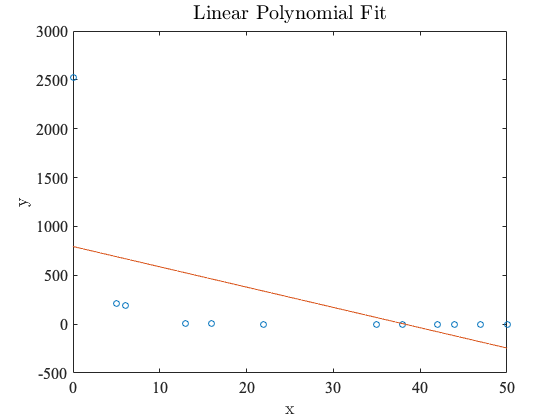

plot_polynomial_fit(x, y, a, 'Linear Polynomial Fit')

% Cubic polynomial fit
[a, error] = polynomial_least_squares(x, y, 3)

a = 	1.0e+03 *

    1.9493
   -0.2717
    0.0100
   -0.0001


error = 3.0460e+03

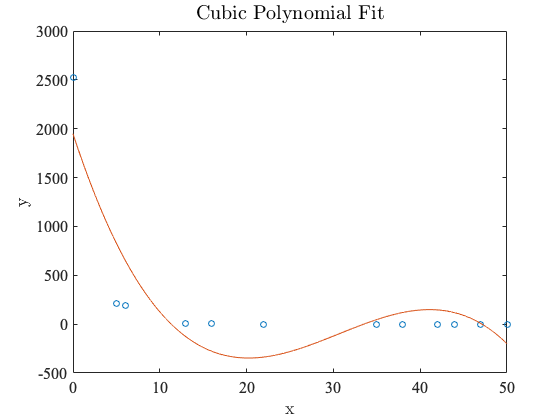

plot_polynomial_fit(x, y, a, 'Cubic Polynomial Fit')

% Linear polynomial fit to the "linearized" data
[a, error] = exponential_least_squares(x, y, 'linearized')

a = 	1.0e+03 *

    3.0138
   -0.0005


error = 567.9959

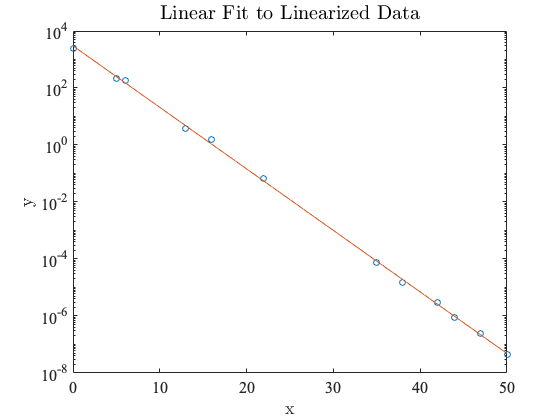

plot_exponential_fit(x, y, a(2), a(1), 'Linear Fit to Linearized Data')

% Non-linear exponential fit
[a_nonlinear, error] = exponential_least_squares(x, y, 'nonlinear')

a_nonlinear = 	1.0e+03 *

    2.5233
   -0.0005


error = 69.9917

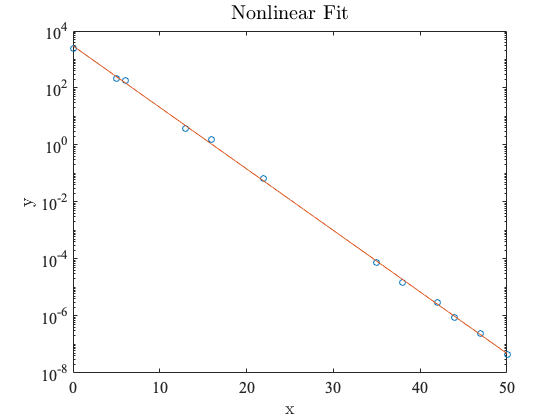

plot_exponential_fit(x, y, a(2), a(1), 'Nonlinear Fit')

## 2.

### i.

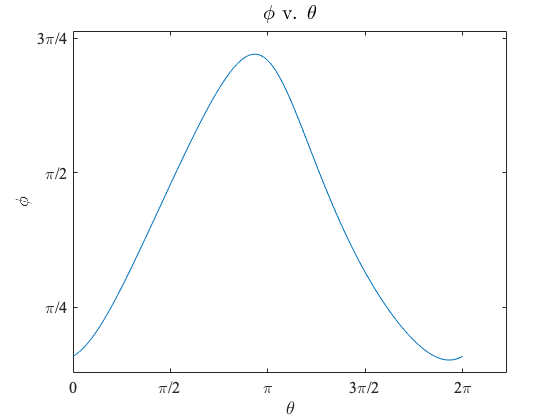

% Define constants
TOL = 1e-10;
MAX_ITER = 20;

DC = 7;
CB = 2.36;
AB = 6.86;
DA = 1.84;

syms phi theta3;

% Stores [φ θ]
phi_theta3 = zeros(2, 362);

% Initial guess for θ = 0
phi_theta3(:, 1) = [deg2rad(28.5); deg2rad(208)];

for theta = 0 : 360
    theta4 = deg2rad(theta + 180);

    F = [
        CB * cos(phi) + AB * cos(theta3) + DA * cos(theta4) - DC;
        CB * sin(phi) + AB * sin(theta3) + DA * sin(theta4)
    ];
    
    % Use previously found solution as initial starting guess
    phi_theta3(:, theta + 2) = nonlinear_newton(F, [phi; theta3], phi_theta3(:, theta + 1), MAX_ITER, TOL);
end

% Plot φ v. θ
phi = mod(phi_theta3(1, 2:end), 2 * pi);

f = figure;
plot(deg2rad(0:1:360), phi)

radians_xtickmarks
radians_ytickmarks
label_figure(f, '$\phi$ v. $\theta$', '$\theta$', '$\phi$', {});

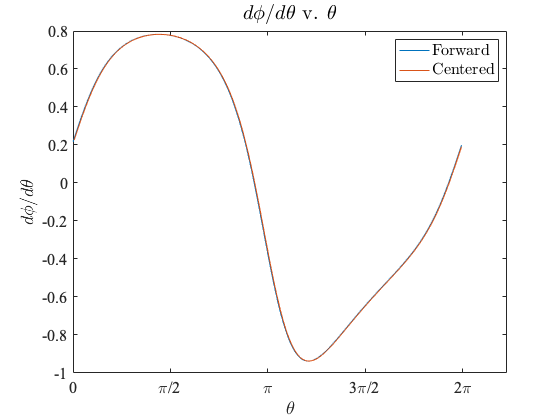

% Calculate dφ/dθ with a first forward difference 
dphi_dtheta_forward = forward_difference(phi, deg2rad(1), 1);

% Calculate dφ/dθ with a center difference approximation
dphi_dtheta_centered = centered_difference(phi, deg2rad(1), 1);

% Plot both curves on the same graph
plot_forward_centered(deg2rad(0:1:359), dphi_dtheta_forward, ...
                      deg2rad(1:1:359), dphi_dtheta_centered, ...
                      '$\theta$', '$d\phi/d\theta$')
radians_xtickmarks

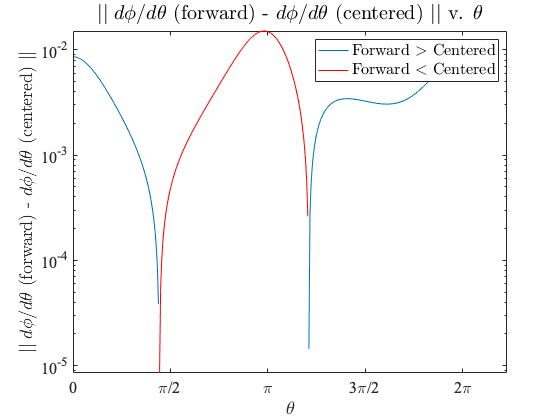


% Plot difference between forward and centered
plot_difference(dphi_dtheta_forward(2:end), ...
                dphi_dtheta_centered, ...
                deg2rad(1:1:359), ...
                '$\theta$', ...
                '$\mid\mid d\phi/d\theta$ (forward) - $d\phi/d\theta$ (centered) $\mid\mid$')
radians_xtickmarks

### ii.

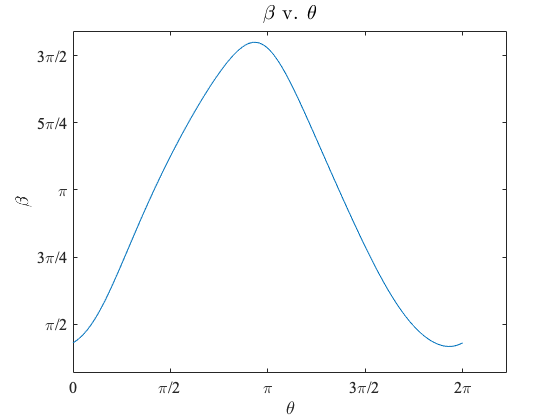

% Define constants
TOL = 1e-10;
MAX_ITER = 20;

CG = 1.25;
GF = 1.26;
EF = 1.82;
CE = 2.41;

syms beta theta3;

% Stores [β θ3]
beta_theta3 = zeros(2, 362);

% Initial guess for θ = 0
beta_theta3(:, 1) = [deg2rad(78); deg2rad(218.5)];

% Use Newton's method on the second linkage system to compute β
for i = 1 : 361
    theta4 = phi(i) + deg2rad(149 + 180);
    
    F = [
        GF * cos(beta) + EF * cos(theta3) + CE * cos(theta4) - CG;
        GF * sin(beta) + EF * sin(theta3) + CE * sin(theta4)
    ];

    % Use previously found solution as initial starting guess
    beta_theta3(:, i+1) = nonlinear_newton(F, [beta; theta3], beta_theta3(:, i), MAX_ITER, TOL);
end

% Plot β v. θ
beta = mod(beta_theta3(1, 2:end), 2 * pi);

f = figure;
plot(deg2rad(0:1:360), beta);

radians_xtickmarks
radians_ytickmarks
label_figure(f, '$\beta$ v. $\theta$', '$\theta$', '$\beta$', {})

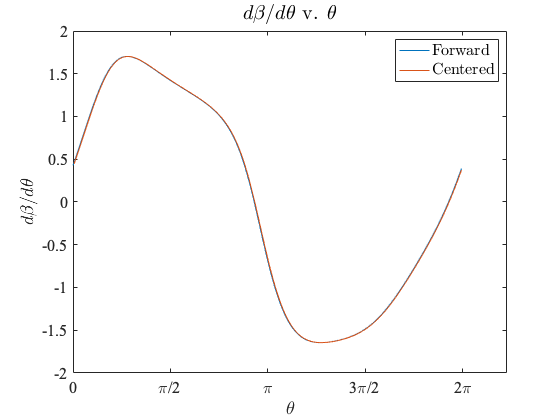

% Calculate dβ/dθ with a first forward difference 
dbeta_dtheta_forward = forward_difference(beta, deg2rad(1), 1);

% Calculate dβ/dθ with a center difference approximation
dbeta_dtheta_centered = centered_difference(beta, deg2rad(1), 1);

% Plot both dβ/dθ curves on the same graph
plot_forward_centered(deg2rad(0:1:359), dbeta_dtheta_forward, ...
                      deg2rad(1:1:359), dbeta_dtheta_centered, ...
                      '$\theta$', '$d\beta/d\theta$')
radians_xtickmarks           

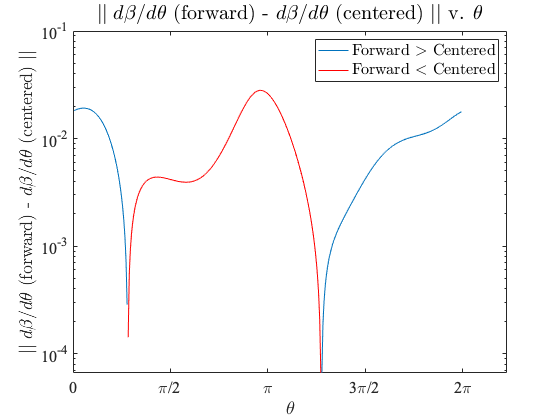


% Plot differences between dβ/dθ forward and centered
plot_difference(dbeta_dtheta_forward(2:end), ...
                dbeta_dtheta_centered, ...
                deg2rad(1:1:359), ...
                '$\theta$', ...
                '$\mid\mid d\beta/d\theta$ (forward) - $d\beta/d\theta$ (centered) $\mid\mid$')
radians_xtickmarks 

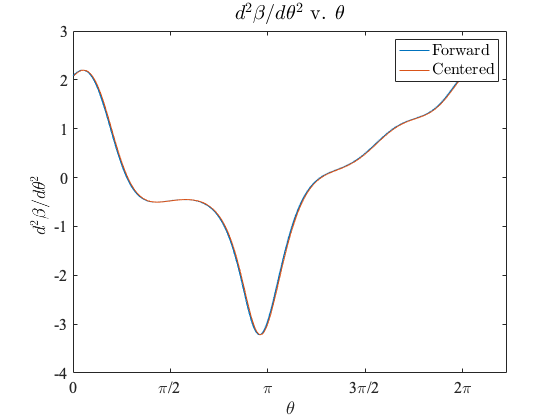

% Calculate d2β/dθ2 with a second forward difference 
d2beta_dtheta2_forward = forward_difference(beta, deg2rad(1), 2);

% Calculate d2β/dθ2 with a center difference approximation
d2beta_dtheta2_centered = centered_difference(beta, deg2rad(1), 2);

% Plot both d2β/dθ2 curves on the same graph
plot_forward_centered(deg2rad(0:1:358), d2beta_dtheta2_forward, ...
                      deg2rad(1:1:359), d2beta_dtheta2_centered, ...
                      '$\theta$', '$d^2\beta/d\theta^2$ ')
radians_xtickmarks

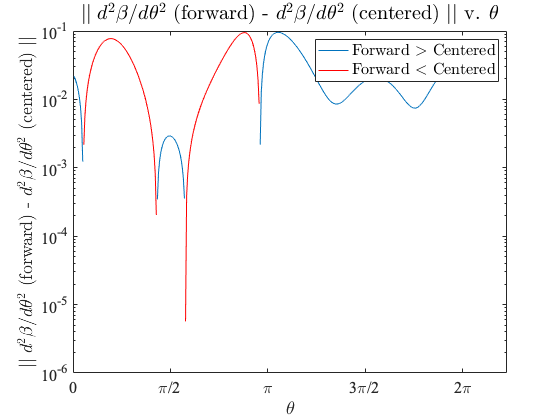


% Plot differences between forward and centered for d2β/dθ2
plot_difference(d2beta_dtheta2_forward(2:end), ...
                d2beta_dtheta2_centered(1:end-1), ...
                deg2rad(1:1:358), ...
                '$\theta$', '$\mid\mid d^2\beta/d\theta^2$ (forward) - $d^2\beta/d\theta^2$ (centered) $\mid\mid$')
radians_xtickmarks

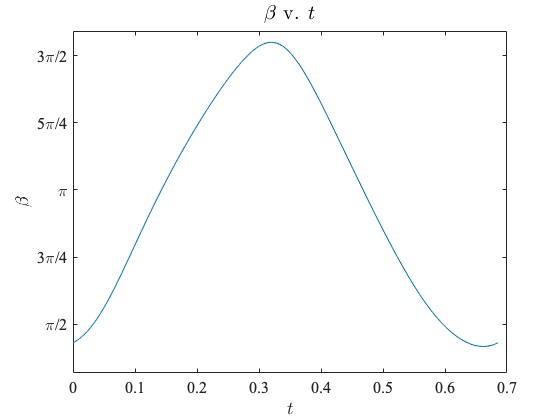

w_rad_min = 550;        % radians per minute
w_rad_sec = 550 / 60;   % radians per second

t = deg2rad(0:1:360) / w_rad_sec;

% β v. t
f = figure;
plot(t, beta);
radians_ytickmarks
label_figure(f, '$\beta$ v. $t$', '$t$', '$\beta$', {})

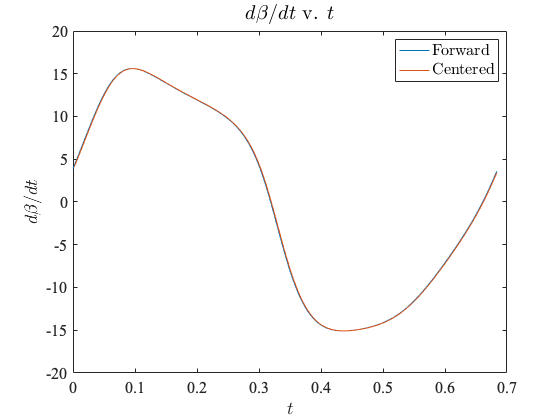


% Forward dβ/dt
dbeta_dt_forward = dbeta_dtheta_forward * w_rad_sec;

% Centered dβ/dt
dbeta_dt_centered = dbeta_dtheta_centered * w_rad_sec;

% Plot both dβ/dt curves on the same graph
plot_forward_centered(t(1:360), dbeta_dt_forward, ...
                      t(2:360), dbeta_dt_centered, ...
                      '$t$', '$d\beta/dt$')

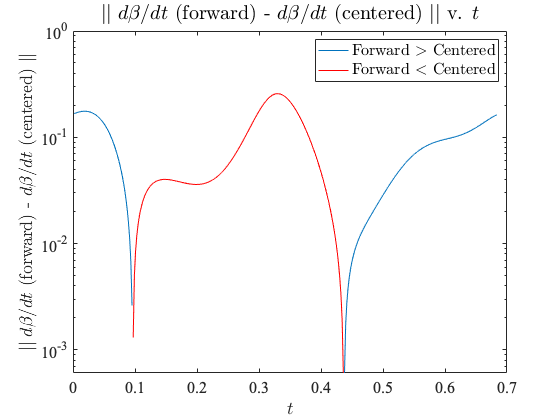

                  
% Plot difference between forward and centered for dβ/dt
plot_difference(dbeta_dt_forward(2:end), ...
                dbeta_dt_centered, ...
                t(2:360), ...
                '$t$', '$\mid\mid d\beta/dt$ (forward) - $d\beta/dt$ (centered) $\mid\mid$')

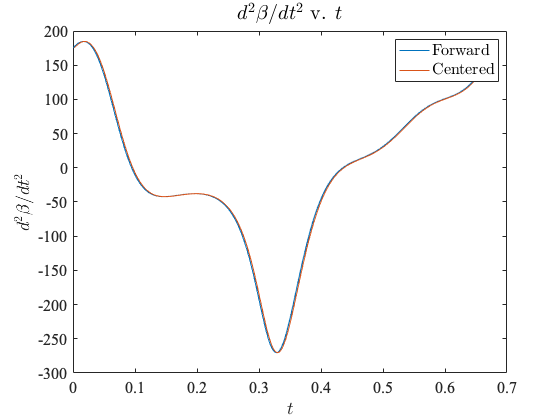

% Forward d2β/dt2
d2beta_dt2_forward = d2beta_dtheta2_forward * w_rad_sec^2;

% Center d2β/dt2
d2beta_dt2_centered = d2beta_dtheta2_centered * w_rad_sec^2;

% Plot both d2β/dt2 curves on the same graph
plot_forward_centered(t(1:359), d2beta_dt2_forward, ...
                      t(2:360), d2beta_dt2_centered, ...
                      '$t$', '$d^2\beta/dt^2$')

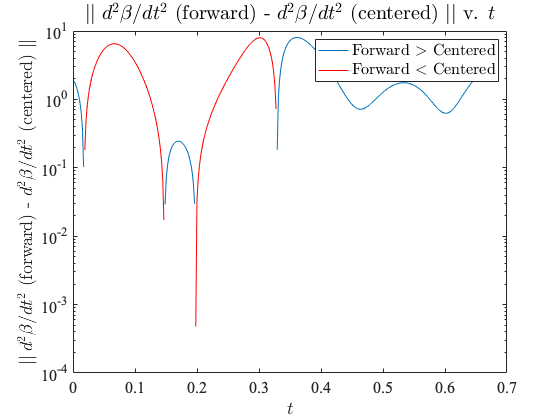

                  
% Plot differences between forward and centered for d2β/dt2
plot_difference(d2beta_dt2_forward(2:end), ...
                d2beta_dt2_centered(1:end-1), ...
                t(2:359), ...
                '$t$', '$\mid\mid d^2\beta/dt^2$ (forward) - $d^2\beta/dt^2$ (centered) $\mid\mid$')

## Functions

function radians_xtickmarks
    xticks([0 pi/2 pi 3*pi/2 2*pi])
    xticklabels({'0','\pi/2','\pi','3\pi/2' '2\pi'})
end

function radians_ytickmarks
    yticks([0 pi/4 pi/2 3*pi/4 pi, 5*pi/4, 3*pi/2, 2*pi])
    yticklabels({'0','\pi/4','\pi/2','3\pi/4' '\pi', '5\pi/4', '3\pi/2', '2\pi'})
end

function label_figure(f, title_text, x_label, y_label, legend_labels)
    %{
        Labels a figure with specified font style.
        
        Input:
            f: figure
            title_text: title
            x_label: x axis label
            y_label: y axis label
            legend_labels: legend keys
    %}
    
    set(f, 'DefaultTextInterpreter', 'latex');  
    set(f, 'DefaultAxesTickLabelInterpreter', 'latex');  
    set(f, 'DefaultLegendInterpreter', 'latex');
    
    ax = gca(f);
    ax.XAxis.FontSize = 16;
    ax.XAxis.FontName = 'Times New Roman';
    
    ax.YAxis.FontSize = 16;
    ax.YAxis.FontName = 'Times New Roman';
    
    title(title_text, 'FontSize', 20, 'FontWeight', 'normal');
    xlabel(x_label);
    ylabel(y_label);
    
    if ~isempty(legend_labels)
        legend(legend_labels, 'FontSize', 16);
    end
end

function plot_forward_centered(xf, yf, xc, yc, x_label, y_label)
    %{
        Plots forward and centered approximations on the same graph.
        
        Input:
            xf: x values for the forward approximation
            yf: y values for the forward approximation
            xc: x values for the centered approximation
            yc: y values for the centered approximation
            x_label: x axis label
            y_label: y axis label
    %}
    
    title_text = sprintf('%s v. %s', y_label, x_label);
    
    f = figure;
    plot(xf, yf, xc, yc);
    label_figure(f, title_text, x_label, y_label, {'Forward', 'Centered'});
end

function plot_difference(y1, y2, x, x_label, y_label)
    %{
        Plots absolute differences between two curves y1 and y2.
        Positive differences are y1 - y2 > 0.

        Input:
            y1: first set of y values
            y2: second set of y values
            x: shared x values
            x_label: x axis label
            y_label: y axis label
    %}
    
    diff = y1 - y2;

    diff_positive = diff;
    diff_positive(diff < 0) = NaN;

    diff_negative = diff;
    diff_negative(diff > 0) = NaN;
    
    title_text = sprintf('%s v. %s', y_label, x_label);

    f = figure;
    plot(x, diff_positive, x, abs(diff_negative), 'r')
    set(gca, 'YScale', 'log')
    label_figure(f, title_text, x_label, y_label, {'Forward $>$ Centered', 'Forward $<$ Centered'});
end

function a = forward_difference(y, h, order)
    %{
        Calculates forward differences.
        
        Input:
            y: y values
            h: step size
            order: 1 for first derivative, 2 for second
        
        Returns:
            a: array of forward differences
    %}
    
    switch order
        case 1
            n = length(y) - 1;
            a = zeros(n, 1);
    
            for j = 1 : n
                a(j) = (y(j+1) - y(j)) / h;
            end
        
        case 2
            n = length(y) - 2;
            a = zeros(n, 1);

            for j = 1 : n
                a(j) = (y(j) - 2 * y(j+1) + y(j+2)) / h^2;
            end
    end
end

function a = centered_difference(y, h, order)
    %{
        Calculates centered differences.
        
        Input:
            y: y values
            h: step size
            order: 1 for first derivative, 2 for second

        Returns:
            a: array of centered differences
    %}
    
    n = length(y) - 1;
    a = zeros(n-1, 1);
    
    switch order
        case 1
            for j = 2 : n
                a(j-1) = (y(j+1) - y(j-1)) / (2 * h);
            end
        
        case 2
            for j = 2 : n
                a(j-1) = (y(j-1) - 2 * y(j) + y(j+1)) / h^2;
            end
    end
end

function err = absolute_error(x, xh)
    % Returns sum of absolute errors.
    err = sum(abs(x - xh));
end

function [a, err] = polynomial_least_squares(x, y, n)
    %{
        Polynomial least squares approximation.
        
        Input:
            x: x values
            y: y values
            n: order of approximating polynomial
        
        Returns:
            a: coefficients of the least squares polynomial
                P_n(x) = a_0 + a_1 * x + ... + a_n * x^n
            err: sum of absolute errors
    %}

    X = zeros(n+1, n+1);
    b = zeros(n+1, 1);
   
    for k = 0 : n
        for j = 0 : n
            X(k + 1, j + 1) = sum(x.^(k + j));        
        end
        
        b(k + 1) = sum(y .* x.^k);
    end  
    
    % Solve for a
    a = X\b;
    
    % Calculate error
    yh = polyval(flip(a, 1), x);
    err = absolute_error(y, yh);

end

function [a, err] = exponential_least_squares(x, y, type)
    %{
        Exponential least squares approximation.
        Fits y = be^(ax) to the data.
        
        Input:
            x: x values
            y: y values
            type: 'linearized' or 'nonlinear'
        
        Returns:
            a: [a b]
            err: sum of absolute errors
    %}

    % Linearized system: lny = lnb + ax
   lny = log(y);

   % a = [lnb a]
   a = polynomial_least_squares(x, lny, 1);
   
   % b = e^lnb
   a(1) = exp(a(1));

   if strcmp(type, 'nonlinear')
      syms c d;

      F = [
           d * sum(exp(2 * c .* x)) - sum(y .* exp(c .* x));
           d * sum(x .* exp(2 * c .* x)) - sum(x .* y .* exp(c .* x))
      ];

      % Use linearized result as p0
      a = nonlinear_newton(F, [d; c], a, 20, 1e-10);
   end
    
   % Calculate error
   yh = a(1) .* exp(a(2) .* x);
   err = absolute_error(y, yh);

end

function p = nonlinear_newton(F, vars, p0, max_iter, tol)
    %{
        Newton's method for a nonlinear system.
        Based on Homework 2. 
        
        Input:
            F: nx1 array of functions
            vars: nx1 array of input variables for F
            p0: initial guess
            max_iter: max number of iterations
            tol: tolerance
    
        Returns:
            p: approximation of p
    %}

    error = 0;
    
    J = jacobian(F, vars);
    y = J\F;
    
    for n = 1 : max_iter
        p = p0 - eval(subs(y, vars, p0));
      
        % Relative error
        error = norm(p - p0)/norm(p);
        
        if (error < tol)
            break;
        end

        p0 = p;
    end
end

function plot_polynomial_fit(x, y, a, title_text)
    %{
        Plots a polynomial fit to data.
        
        Input:
            x: x values
            y: y values
            a: coefficients of polynomial, [a0 ... an]
            title_text: graph title
    %}
    
    % Generate plotting points
    xx = min(x):1e-3:max(x);
    yy = polyval(flip(a, 1), xx);
    
    f = figure;
    plot(x, y, 'o', xx, yy)
    
    label_figure(f, title_text, 'x', 'y', {});
end

function plot_exponential_fit(x, y, a, b, title_text)
    %{
        Plots an exponential fit to data, y = be^(ax)
        
        Input:
            x: x values
            y: y values
            a: constant in power
            b: multiplying constant
            title_text: graph title
    %}

    % Generate plotting points
    xx = min(x):1e-3:max(x);
    yy = b .* exp(a .* xx);
    
    f = figure;
    plot(x, y, 'o', xx, yy)
    set(gca, 'YScale', 'log')
    
    label_figure(f, title_text, 'x', 'y', {});
end